% Define paths to your depth and color images
depthImageFile ="C:\Users\moham\Desktop\Kings\individual\Python\Yolo_V8\masked_depth_image.png";
colorImageFile ="C:\Users\moham\Desktop\Kings\individual\Python\Yolo_V8\masked_image.png"

colorImageFile = "C:\Users\moham\Desktop\Kings\individual\Python\Yolo_V8\masked_image.png"

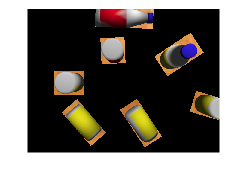

% Load images
depthImage = imread(depthImageFile);  % Assuming 16-bit unsigned or similar
colorImage = imread(colorImageFile);
colorImage = im2uint8(colorImage);  % Convert to uint8 if not already
colorImage = colorImage(:,:,[1 2 3]);  % Convert from BGR to RGB (OpenCV to MATLAB style)
imshow(colorImage)

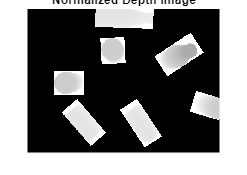

% Normalize depth image for display
normalizedDepth = mat2gray(depthImage);
figure;
imshow(normalizedDepth);
title('Normalized Depth Image');

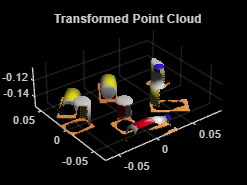


% Ensure both images have the same dimensions
if size(depthImage, 1) ~= size(colorImage, 1) || size(depthImage, 2) ~= size(colorImage, 2)
    depthImage = imresize(depthImage, [size(colorImage, 1), size(colorImage, 2)], 'nearest');
end

% Convert depth to meters
depthScale = 1000.0;  % Assuming depth is in millimeters
depthImageMeters = double(depthImage) / depthScale;

% Image dimensions
[height, width] = size(depthImageMeters);

% Generate meshgrid for pixel coordinates
[u, v] = meshgrid(1:width, 1:height);

% Define camera intrinsics
fx = 535.4; fy = 539.2;
cx = 320.1; cy = 247.6;

% Back-project to 3D space
X = (u - cx) .* depthImageMeters / fx;
Y = (v - cy) .* depthImageMeters / fy;
Z = depthImageMeters;

% Concatenate X, Y, Z into a single M-by-N-by-3 array
xyzPoints = cat(3, X, Y, Z);

% Check for invalid depth and set to NaN
invalidDepth = (depthImageMeters == 0);
xyzPoints(repmat(invalidDepth, [1 1 3])) = NaN;

% Create a point cloud object
ptCloud = pointCloud(xyzPoints, 'Color', colorImage);

% Flip the Z-axis
tform = affine3d([1 0 0 0; 0 1 0 0; 0 0 -1 0; 0 0 0 1]);
ptCloud = pctransform(ptCloud, tform);

% Visualize the point cloud
figure;
pcshow(ptCloud);
title('Transformed Point Cloud');

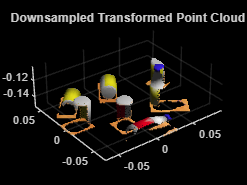


% Downsample the point cloud
gridSize = 0.0006;  % Size of the grid to downsample
ptCloudDownsampled = pcdownsample(ptCloud, 'gridAverage', gridSize);

% Visualize the downsampled point cloud
figure;
pcshow(ptCloudDownsampled);
title('Downsampled Transformed Point Cloud');

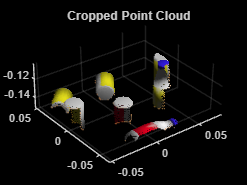

Cropped point cloud has 13718 points.


Cropped point cloud saved to 'C:\Users\moham\Desktop\Kings\individual\Matlab\cropped_point_cloud.ply'.


% Define the Z-axis cropping thresholds (in meters)
zMinThreshold = -0.152;  % Minimum Z value
zMaxThreshold = -0.1;   % Maximum Z value

% Extract the XYZ point data and color data
points = ptCloudDownsampled.Location;
colors = ptCloudDownsampled.Color;

% Identify points within the specified Z range
validIndices = points(:, 3) >= zMinThreshold & points(:, 3) <= zMaxThreshold;

% Filter points and colors based on valid indices
croppedPoints = points(validIndices, :);
croppedColors = colors(validIndices, :);

% Create a new point cloud with the cropped points and associated colors
croppedPointCloud = pointCloud(croppedPoints, 'Color', croppedColors);

% Visualize the cropped point cloud
if croppedPointCloud.Count > 0
    figure;
    pcshow(croppedPointCloud);
    title('Cropped Point Cloud');
    disp(['Cropped point cloud has ', num2str(croppedPointCloud.Count), ' points.']);

    % Optionally, save the cropped point cloud
    croppedOutputPath = 'C:\Users\moham\Desktop\Kings\individual\Matlab\cropped_point_cloud.ply';
    pcwrite(croppedPointCloud, croppedOutputPath, 'Encoding', 'binary');
    disp(['Cropped point cloud saved to ''', croppedOutputPath, '''.']);
else
    disp('Cropped point cloud has 0 points. Please adjust the Z-axis thresholds.');
end

% Scale the point cloud
scaleFactor = 4;
scaledPoints = croppedPointCloud.Location * scaleFactor;

% Create a new point cloud with the scaled points and original colors
scaledPointCloud = pointCloud(scaledPoints, 'Color', croppedPointCloud.Color);

% Generate the output file path
[path, name, ext] = fileparts(croppedOutputPath);
scaledOutputPath = fullfile(path, [name, '_scaled_', num2str(scaleFactor, '%.3f'), ext]);

% Write the scaled point cloud to the new file
pcwrite(scaledPointCloud, scaledOutputPath, 'Encoding', 'binary');
disp(['Saved scaled point cloud to ', scaledOutputPath]);

Saved scaled point cloud to C:\Users\moham\Desktop\Kings\individual\Matlab\cropped_point_cloud_scaled_4.000.ply


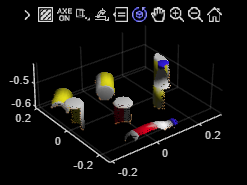



% Visualize the scaled point cloud
figure;
pcshow(scaledPointCloud);
title('Scaled Point Cloud');

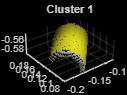

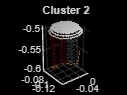

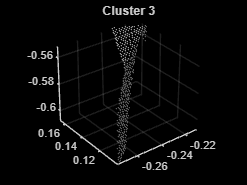

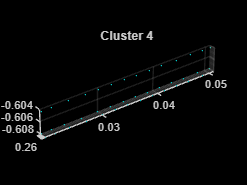

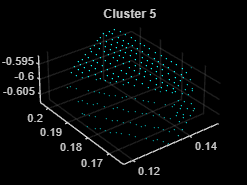

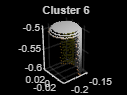

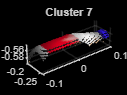

% Perform hierarchical clustering (agglomerative clustering) on the scaled point cloud
distanceThreshold = 0.03; % Distance threshold for merging clusters
clusters = clusterdata(scaledPointCloud.Location, 'cutoff', distanceThreshold, 'criterion', 'distance');

% Visualize each cluster separately
numClusters = max(clusters);
colors = lines(numClusters);
for i = 1:numClusters
    clusterIndices = find(clusters == i);
    clusterPointCloud = pointCloud(scaledPointCloud.Location(clusterIndices, :), 'Color', scaledPointCloud.Color(clusterIndices, :));
    figure;
    pcshow(clusterPointCloud.Location, clusterPointCloud.Color);
    title(['Cluster ', num2str(i)]);
end

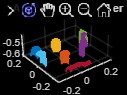



% Combine all clustered point clouds
combinedPointCloud = [];
combinedColors = [];
for i = 1:numClusters
    clusterIndices = find(clusters == i);
    combinedPointCloud = [combinedPointCloud; scaledPointCloud.Location(clusterIndices, :)];
    combinedColors = [combinedColors; repmat(colors(i, :), length(clusterIndices), 1)];
end

% Visualize all clusters together
figure;
pcshow(combinedPointCloud, combinedColors);
title('All Clusters Together');

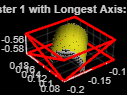

Longest axis for cluster 1: Y-axis (0.12248 meters)


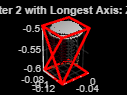

Longest axis for cluster 2: Z-axis (0.108 meters)


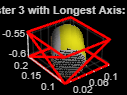

Longest axis for cluster 3: Y-axis (0.13004 meters)


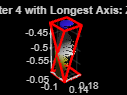

Longest axis for cluster 4: Z-axis (0.176 meters)


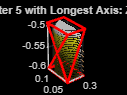

Longest axis for cluster 5: Z-axis (0.112 meters)


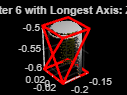

Longest axis for cluster 6: Z-axis (0.108 meters)


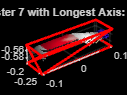

Longest axis for cluster 7: X-axis (0.20601 meters)


% Assuming clusters have already been identified in the `clusters` variable
numClusters = max(clusters); % Determine the number of clusters
colors = lines(numClusters); % Generate unique colors for each cluster

% Initialize storage for the longest axis of each bounding box
bboxDimensions = zeros(numClusters, 3);
longestAxisLengths = zeros(numClusters, 1);
longestAxisNames = {'X-axis', 'Y-axis', 'Z-axis'}; % Correctly define as a cell array of strings

for i = 1:numClusters
    clusterIndices = clusters == i;
    clusterPoints = scaledPointCloud.Location(clusterIndices, :);
    clusterColors = scaledPointCloud.Color(clusterIndices, :);

    % Calculate the bounding box for the current cluster
    minX = min(clusterPoints(:,1));
    maxX = max(clusterPoints(:,1));
    minY = min(clusterPoints(:,2));
    maxY = max(clusterPoints(:,2));
    minZ = min(clusterPoints(:,3));
    maxZ = max(clusterPoints(:,3));

    % Dimensions of the bounding box [width, height, depth]
    width = maxX - minX;
    height = maxY - minY;
    depth = maxZ - minZ;
    bboxDimensions(i, :) = [width, height, depth];

    % Determine the longest axis in the bounding box
    [longestAxisLengths(i), idx] = max(bboxDimensions(i, :));
    longestAxis = longestAxisNames{idx};  % Access the correct axis name using curly braces

    % Create the point cloud for the current cluster
    clusterPointCloud = pointCloud(clusterPoints, 'Color', clusterColors);

    % Visualize the current cluster
    figure;
    pcshow(clusterPointCloud);
    title(['Cluster ', num2str(i), ' with Longest Axis: ', longestAxis]);

    % Drawing the bounding box for visualization
    bboxCorners = [minX, minY, minZ; maxX, minY, minZ; maxX, maxY, minZ; minX, maxY, minZ; ...
                   minX, minY, maxZ; maxX, minY, maxZ; maxX, maxY, maxZ; minX, maxY, maxZ];
    bboxLines = [bboxCorners(1,:), bboxCorners(2,:); bboxCorners(2,:), bboxCorners(3,:); bboxCorners(3,:), bboxCorners(4,:); bboxCorners(4,:), bboxCorners(1,:); ...
                 bboxCorners(5,:), bboxCorners(6,:); bboxCorners(6,:), bboxCorners(7,:); bboxCorners(7,:), bboxCorners(8,:); bboxCorners(8,:), bboxCorners(5,:); ...
                 bboxCorners(1,:), bboxCorners(5,:); bboxCorners(2,:), bboxCorners(6,:); bboxCorners(3,:), bboxCorners(7,:); bboxCorners(4,:), bboxCorners(8,:)];
    hold on;
    plot3(bboxLines(:, [1,4]), bboxLines(:, [2,5]), bboxLines(:, [3,6]), 'r-', 'LineWidth', 2);
    hold off;
    
    % Display longest axis info
    disp(['Longest axis for cluster ', num2str(i), ': ', longestAxis, ' (', num2str(longestAxisLengths(i)), ' meters)']);
end